# DoE Generator Live Script

## Create structure listing identification parameters

The Fouling Model Simulation Code is supplied with 3 structures which configure the model for each simulation run:

- ***BoundCond***: supplies the boundary conditions for the simulation.

- ***ModelPara***: defines the identification para                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        meter settings for the current simulation.

- ***Options***: enables or disables the soot deposit and removal mechanisms and the HC and water condensation and evaporiasation models.

Note, distributed parameters are represented as B-splines for compactness and are automatically converted to lookup tables by the code. 

## Configure duct geometry and number of tubes

clear;
clc;

DuctGeometry = "Circle";    % Duct interior geometry
InteriorDia = 4.5;     % Clean tube interior (or hydraulic) diameter [mm]
NumberOfTubes = 35;   % Number of tubes
TubeLength = 185;      % Length of tube [mm]

## Configure Parameters or Boundary Conditions to be Estimated from Data

F(1).Name = "fRegMP";               % Friction factor regression parameters
F(1).Units = "[]";
F(1).Fixed = true;                  % Fixed parameter 
F(1).Lo = [ 0.65, -1.25, 0.15 ];
F(1).Hi = [ 1.05, -0.75, 0.95];
F(1).Sz = [1,3];
F(1).Type = "Parameter";
F(1).Spline = struct.empty( 0, 5 );
F(2).Name = "NuRegMP";              % Nusselt number regression parameters
F(2).Units = "";
F(2).Fixed = true;                  % Fixed parameter  
F(2).Lo = [ 0.40, 0.20, 0.60];
F(2).Hi = [ 1.20, 0.80, 1.60 ];
F(2).Sz = [1,3]; 
F(2).Type = "Parameter";
F(2).Spline = struct.empty( 0, 5 );

## Enable/Disable B-Spline Derivative Constraints

***Con*** is a multi-dimensional structure specifiying the necessary constraints. The structure must have the fields:

Name              -->  parameter or boundary condition name

derivative        --> set to 1 or 2 to specify the spline derivative to which the constraint applies.

type                --> set to '==','>=' or '<='

value             --> constraint bound value

x                    --> Axial coordinates at which constraints apply. Leave empty to specify all training x-ordinates

For example, imagine we require to constrain the second derivative of the initial deposit layer thickness (soot_phi0) to be greater or equal to zero everywhere. Then set:

Con(1).name = 'soot_phi0';

Con(1).derivative = 2;

Con(1).type = '>=';

Con(1).value = 0;

Con(1).x = [];

Con = struct.empty;

## Set number of computational cells for the simulation & whether cooler is initially clean. 

The more cells you have the more accurate the simulation results, at the expense of computational expense. In our experience, 10 - 20 is a good compromise.

NumComputationalCells = 10;
CleanCooler =  true;

## Configue the ECOMO User Interface Object and Run the Initial Experiment

UseParallel = true;
obj = ECOMOuserInterface( "TubeDia", InteriorDia, "TubeLen", TubeLength, "NumTubes", NumberOfTubes,...
    "TubeGeo", DuctGeometry, "Parallel", UseParallel, "Clean", CleanCooler );
obj = obj.defineFactors( F, struct.empty );
%-----------------------------------------------------------------
% Design size is user selectable and sequence should be scrambled.
%
% "Leap" refers to gap in the standard sequence between selected
% points: Make a relatively large prime number.
%
% "Skip" refers to the number of initial points in the standard
% sequence to omit before point selection. Inital points may have
% undersirable properties (e.g. strong correlation among terms)
%-----------------------------------------------------------------
DesignSize = 250;
Leap = max( primes( 1770 ) );
Skip =  max( primes( 13800 ) ); 
obj = obj.generateDesign( DesignSize, "Scramble", true, "Leap", Leap, "Skip", Skip );
%-----------------------------------------------------------------------
% Configure the Bayesian Optimisation surrogate model and acquisition 
% function. Run the simulation and build the surrogate model
%-----------------------------------------------------------------------
SurrogateModel = "gpr";
AcqFcn = "ucb";
%-----------------------------------------------------------------------
% Define name of variable containing identification data
%-----------------------------------------------------------------------
StructName = "CharTVars3";
%-----------------------------------------------------------------------
% Set cost function:
%
% Pressure    --> cost function is a function of delta pressure only
% Temperature --> cost function is a function of outlet temperature only
% Combined    --> cost function is a function of both pressure and 
%                 temperature measures.
%-----------------------------------------------------------------------
CostFcn = "Combined";
obj = obj.setCostFcn( CostFcn );
tic;
obj = obj.runSimulation( SurrogateModel, AcqFcn, NumComputationalCells, StructName );

run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  200 / 659 ----------------

toc;

Elapsed time is 164.308956 seconds.


## Set the exploration rate multiplier. Provides the user with an easy way of increasing or decreasing the amount of explorationversus exploitation. The larger the multiplier the more explanatory the search.

ExplorationMult = 10;
obj = obj.setExploreGain( ExplorationMult );

## Minimise the BO Acquisition Function Iteratively and Plot the Results  

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    6.864719e+03    0.000e+00    2.804e+03
    1      17    6.841196e+03    0.000e+00    8.715e+03    5.598e-02
    2      27    6.780373e+03    0.000e+00    6.827e+03    4.962e-02
    3      37    6.728596e+03    0.000e+00    8.558e+03    6.960e-02
    4      44    6.364585e+03    0.000e+00    3.742e+03    3.420e-01
    5      53    6.349480e+03    0.000e+00    3.978e+03    2.533e-02
    6      60    6.281199e+03    0.000e+00    2.595e+02    1.715e-01
    7      67    6.279558e+03    0.000e+00    4.163e+02    1.280e-02
    8      74    6.278034e+03    0.000e+00    1.060e+02    2.820e-02
    9      82    6.277675e+03    0.000e+00    4.662e+02    1.348e-02
   10      89    6.277154e+03    0.000e+00    1.139e+02    1.538e-02
   11      96    6.277039e+03    0.000e+00    7.510e+01    9.728e-03
   12     103    6.277046e+03    0.000e+00    1

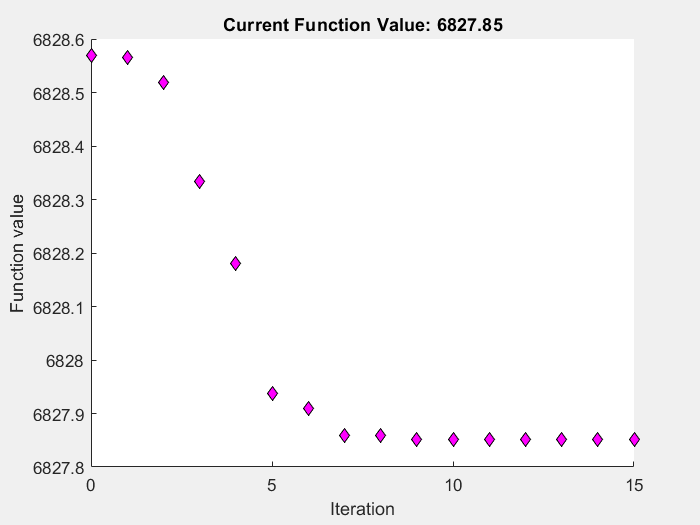

run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  200 / 659 ----------------
run----------------time sereis input: time step:  300 / 659 ----------------
run----------------time sereis input: time step:  400 / 659 ----------------
run----------------time sereis input: time step:  500 / 659 ----------------
run----------------time sereis input: time step:  600 / 659 ----------------


DataBudget = 25;                 % Number of Bayesian Optimisation iterations
ConvCounterLimit = 3;           % Number of identical results for early conversion
tic;
obj = obj.applyBayesianOpt( DataBudget, ConvCounterLimit );

toc;

Elapsed time is 240.403016 seconds.


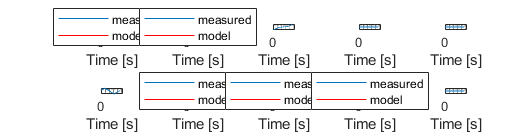

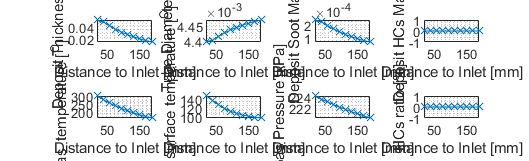

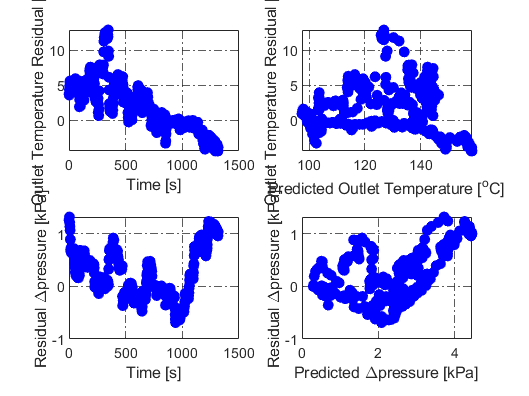

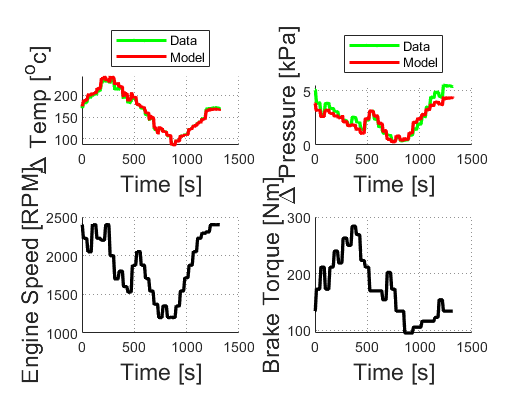

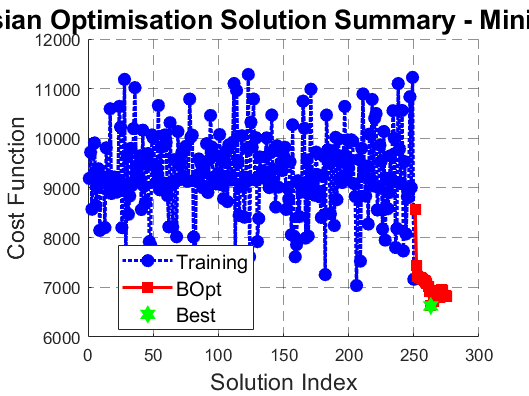

obj.plot;

%-----------------------------------------------------------------------
% Export the results to the workspave
%-----------------------------------------------------------------------
[ FM, ModelPara, BoundCond ] = obj.exportParameters();

## Tabulate the Identified Nu Parameters $N_u =A\ldotp R_e^C \ldotp P_r^D$

Idx = matches( [ F.Name ], "NuRegMP" );
if any( Idx )
    NuReg = ModelPara.NuRegMP;
    Lo = F( Idx ).Lo;
    Hi = F( Idx ).Hi;
    Nu = table( Lo.', NuReg.', Hi.' );
    Nu.Properties.RowNames = [ "A", "C", "D"];
    Nu.Properties.VariableNames = [ "Low", "Value", "High" ];
    disp( Nu )
end

         Low     Value     High
         ___    _______    ____

    A    0.4    0.59103    1.2 
    C    0.2    0.52661    0.8 
    D    0.6    0.82836    1.6 



## Tabulate the Identified $f$ Parameters:

## $f=\frac{D_1 }{R_e },R_e <2300$ (Laminar Flow)

## $f=D_2 \ldotp R_e^E$, $R_e \in \left\lbrack 4000,20000\right\rbrack$ (Turbulent Flow)

Idx = matches( [ F.Name ], "fRegMP" );
if any( Idx )
    NuReg = ModelPara.fRegMP;
    Lo = F( Idx ).Lo;
    Hi = F( Idx ).Hi;
    f = table( Lo.', NuReg.', Hi.' );
    f.Properties.RowNames = [ "D_2", "E", "D_1"];
    f.Properties.VariableNames = [ "Low", "Value", "High" ];
    disp( f )
end

            Low      Value      High 
           _____    ________    _____

    D_2     0.65     0.93484     1.05
    E      -1.25    -0.97135    -0.75
    D_1     0.15     0.54873     0.95



## Configure Parameters or Boundary Conditions to be Estimated from Data

clear F;
F(1).Name = "Distr_Kf";                      % friction factor gain
F(1).Units = "";
F(1).Fixed = false;                         % Fixed parameter
F(1).Lo = 0.25;
F(1).Hi = 2.0;
F(1).Sz = [ 9, 9 ]; 
F(1).Type = "Parameter";
F(1).Spline.M = [3, 3];                    % Tensor product spline parameters
F(1).Spline.K = [1, 1];
F(1).Spline.X = [ "mg_dot", "T_g_in"];     % EGR mass flow and Inlet gas temperature.
F(1).Spline.Xlo = [10, 200];
F(1).Spline.Xhi = [100, 350];
F(2).Name = "Distr_KNu";                      % Nusselt number gain
F(2).Units = "";
F(2).Fixed = false;                         % Fixed parameter
F(2).Lo = 0.75;
F(2).Hi = 1.25;
F(2).Sz = [11, 11]; 
F(2).Type = "Parameter";
F(2).Spline.M = [4, 4];                    % Tensor product spline parameters
F(2).Spline.K = [1, 1];
F(2).Spline.X = [ "mg_dot", "T_g_in"];     % EGR mass flow and Inlet gas temperature.
F(2).Spline.Xlo = [10, 200];
F(2).Spline.Xhi = [100, 350];

## Configue the ECOMO User Interface Object and Run the Initial Experiment

UseParallel = true;
obj = ECOMOuserInterface( "TubeDia", InteriorDia, "TubeLen", TubeLength, "NumTubes", NumberOfTubes,...
    "TubeGeo", DuctGeometry, "Parallel", UseParallel, "Clean", CleanCooler );
obj = obj.defineFactors( F, Con );
%-----------------------------------------------------------------
% Design size is user selectable and sequence should be scrambled.
%
% "Leap" refers to gap in the standard sequence between selected
% points: Make a relatively large prime number.
%
% "Skip" refers to the number of initial points in the standard
% sequence to omit before point selection. Inital points may have
% undersirable properties (e.g. strong correlation among terms)
%-----------------------------------------------------------------
DesignSize = 500;
Leap = max( primes( 1770 ) );
Skip =  max( primes( 13800 ) ); 
obj = obj.generateDesign( DesignSize, "Scramble", true, "Leap", Leap, "Skip", Skip );
%-----------------------------------------------------------------------
% Configure the Bayesian Optimisation surrogate model and acquisition 
% function. Run the simulation and build the surrogate model
%-----------------------------------------------------------------------
SurrogateModel = "gpr";
AcqFcn = "ucb";
%-----------------------------------------------------------------------
% Define name of variable containing identification data
%-----------------------------------------------------------------------
StructName = "CharTVars3";
%-----------------------------------------------------------------------
% Set cost function:
%
% Pressure    --> cost function is a function of delta pressure only
% Temperature --> cost function is a function of outlet temperature only
% Combined    --> cost function is a function of both pressure and 
%                 temperature measures.
%-----------------------------------------------------------------------
CostFcn = "Combined";
obj = obj.setCostFcn( CostFcn );
tic;
obj = obj.runSimulation( SurrogateModel, AcqFcn, StructName, NumComputationalCells );
toc;

## Plot the $K_{N_u }$ Surface

Idx = matches( [ F.Name ], "Distr_KNu" );
if any( Idx )
    T = obj.DoEgenerator.Bspline{ "Distr_KNu", "Object" };
    if iscell( T )
        T = T{ : };
    end
    %------------------------------------------------------------------------------
    % Assign the surface coefficients
    %------------------------------------------------------------------------------
    Alpha = table2array( obj.DoEgenerator.DesignInfo("Distr_KNu", "Coefficients") );
    if iscell( Alpha )
        Alpha = Alpha{ : };
    end
    T = T.setAlpha( obj.EcomoInterface.B.Xbest( Alpha ) );
    %------------------------------------------------------------------------------
    % Assign the knot sequence
    %------------------------------------------------------------------------------
    Knots = table2array( obj.DoEgenerator.DesignInfo("Distr_KNu", "Knots") );
    if iscell( Knots )
        Knots = Knots{ : };
    end
    Knots = obj.EcomoInterface.B.Xbest( Knots );
    Knots = T.convertKnotSequences( Knots );
    T = T.setKnotSequences( Knots );
    AxMesh = T.mesh( 50 );
    AxMesh.XLabel.Interpreter = "latex";
    AxMesh.XLabel.String = "$\dot{m}_{EGR}$ [kg/h/tube]";
    AxMesh.YLabel.String = "T_g [^oC]";
    AxMesh.ZLabel.String = "K_{Nu}";
end

## Plot the $K_f$ Surface

Idx = matches( [ F.Name ], "Distr_Kf" );
if any( Idx )
    T = obj.DoEgenerator.Bspline{ "Distr_Kf", "Object" };
    if iscell( T )
        T = T{ : };
    end
    %------------------------------------------------------------------------------
    % Assign the surface coefficients
    %------------------------------------------------------------------------------
    Alpha = table2array( obj.DoEgenerator.DesignInfo("Distr_Kf", "Coefficients") );
    if iscell( Alpha )
        Alpha = Alpha{ : };
    end
    T = T.setAlpha( obj.EcomoInterface.B.Xbest( Alpha ) );
    %------------------------------------------------------------------------------
    % Assign the knot sequence
    %------------------------------------------------------------------------------
    Knots = table2array( obj.DoEgenerator.DesignInfo("Distr_Kf", "Knots") );
    if iscell( Knots )
        Knots = Knots{ : };
    end
    Knots = obj.EcomoInterface.B.Xbest( Knots );
    Knots = T.convertKnotSequences( Knots );
    T = T.setKnotSequences( Knots );
    AxMesh = T.mesh( 50 );
    AxMesh.XLabel.Interpreter = "latex";
    AxMesh.XLabel.String = "$\dot{m}_{EGR}$ [kg/h]";
    AxMesh.YLabel.String = "T_{g,i} [^oC]";
    AxMesh.ZLabel.String = "K_f";
end